# Practice - ANOVA

## Iris data

*Datasets > DASL > iris.mat*

The data in the iris.mat file are commonly known as Fisher’s iris data. They were originally collected by Anderson in 1935 [Anderson, 1935] and were subsequently analyzed by Fisher in 1936 [Fisher, 1936]. The data set consists of 150 observations, each containing four measurements—sepal length and width, petal length and width—in centimeters. These were collected for three species of iris: Iris setosa, Iris virginica, and Iris versicolor. The goal of the original study was to develop a methodology that could be sed to classify an iris as belonging to one of the three species based on these four variables.

Create a matrix where each column has the observed characteristic for one of the groups.

load iris
% Let's look at sepal width
sepW = [setosa(:,2),virginica(:,2),versicolor(:,2)];

 Perform a one-way ANOVA.

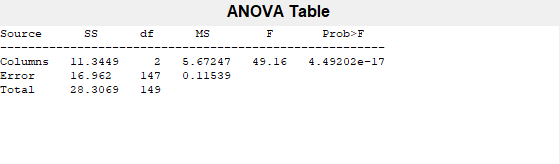

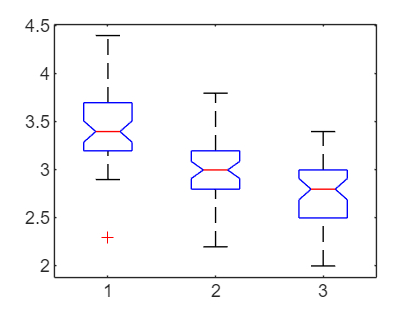

[pval, anova_tbl, stats] = anova1(sepW);

pval

pval = 4.4920e-17

The second window contains side-by-side notched boxplots for the groups. This provides several things. First, it allows us to assess whether our assumptions of normality and equal variance are reasonable, which they seem to be for this example. Second, the notched boxplots give us a visual way to test whether the medians are different. If the intervals given by the notches do not overlap, then we have evidence that the medians are different.

The alternative hypothesis in a one-way ANOVA is that at least one pair of group means is significantly different. However, what pair is different? We can use the multiple comparison test in the Statistics Toolbox to determine which pair is different. Note that it requires the stats output from anova1.

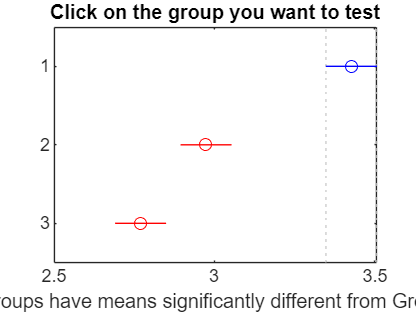

comp =     1.0000    2.0000    0.2948    0.4540    0.6132    0.0000
    1.0000    3.0000    0.4988    0.6580    0.8172    0.0000
    2.0000    3.0000    0.0448    0.2040    0.3632    0.0075


comp = multcompare(stats)

The first two columns of this output represent the group numbers. Thus, the first row is comparing groups 1 and 2, and the last row compares groupsand 3. The third and fifth columns are the end points of a 95% confidence interval for the difference of the group means, and the fourth column is the estimated difference.  The intervals do not contain zero, so we can conclude that these pair of means is significantly different.

## CarBig

carbig =  importdata('carbig.mat')

carbig = struct with fields:
           Model: [406×36 char]
          Origin: [406×7 char]
             MPG: [406×1 double]
       Cylinders: [406×1 double]
    Displacement: [406×1 double]
      Horsepower: [406×1 double]
          Weight: [406×1 double]
    Acceleration: [406×1 double]
      Model_Year: [406×1 double]
            cyl4: [406×5 char]
             org: [406×7 char]
            when: [406×5 char]
             Mfg: [406×13 char]


Convert `Origin` from character arrays with trailing whitespace to string vectors.

carbig.Origin = strtrim(string(carbig.Origin));

Get the 3 countries with the most number of cars. Make a subset out of those cars, which are originated from these countries. 

tabulate(carbig.Origin)

    Value    Count   Percent
      USA      254     62.56%
   France       14      3.45%
    Japan       79     19.46%
  Germany       39      9.61%
   Sweden       11      2.71%
    Italy        8      1.97%
  England        1      0.25%


idx = (carbig.Origin=='USA' | carbig.Origin=='Japan' | ...
    carbig.Origin=='Germany');
subcar = carbig(carbig.Origin(idx),:);

Unable to use a value of type string as an index.

Does Origin effect the consumption (MPG)?

- investigate the conditional boxplot

- make a 1-way anova test

- which country's cars are different in MPG? 

boxplot(subcar.MPG, subcar.Origin)
aov = anova(subcar.Origin ,subcar.MPG)
multcompare(aov)

## Exercise - CarSmall

- load the carsmall dataset

- check if number of cylinders (Cylinders) effects the Acceleration

%